clear
a=[1,0;1,1;3,2;4,3;2,5];
y=pdist(a)   %求a的两两行向量之间的欧氏距离

y =     1.0000    2.8284    4.2426    5.0990    2.2361    3.6056    4.1231    1.4142    3.1623    2.8284


yc=squareform(y)  %变换成距离方阵

yc =          0    1.0000    2.8284    4.2426    5.0990
    1.0000         0    2.2361    3.6056    4.1231
    2.8284    2.2361         0    1.4142    3.1623
    4.2426    3.6056    1.4142         0    2.8284
    5.0990    4.1231    3.1623    2.8284         0


z=linkage(y)   %产生等级聚类树

z =     1.0000    2.0000    1.0000
    3.0000    4.0000    1.4142
    6.0000    7.0000    2.2361
    5.0000    8.0000    2.8284


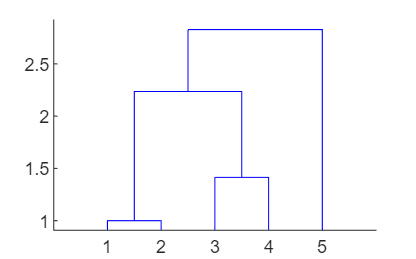

dendrogram(z)   %画聚类图

T=cluster(z,'maxclust',3)  %把对象分成3类

T =      1
     1
     2
     2
     3


for i=1:3
    tm=find(T==i);
    tm=reshape(tm,1,length(tm))
end

tm =      1     2


tm =      3     4


tm = 5